% Load the images
data = load('../data/assignmentImageDenoising_phantom.mat');
noiseless = data.imageNoiseless;
noisy = data.imageNoisy;

[rows,cols] = size(noisy);

noisy = noisy/max(noisy(:));
noiseless = noiseless/max(noiseless(:));

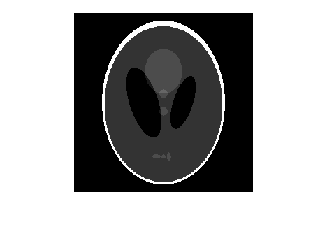

imshow(noiseless);

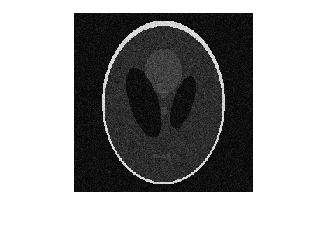

imshow(noisy);

est = noisy;

function noise = log_likelihood(observed, estimate)
    observed(observed == 0) = eps;
    noise = sum(log(observed(:))) - 0.5 * sum(observed(:).^2 + estimate(:).^2) + sum(log(besseli(0, observed(:) .* estimate(:))));
end

function grad = noise_grad(observed, estimate)
    grad = -estimate+besseli(1,observed .* estimate)./besseli(0,observed .* estimate).*observed;
end

function V = quad_log_prior(X)
    diff_x = circshift(X, [0, -1]) - X;
    diff_y = circshift(X, [-1, 0]) - X;
    V = sum(diff_x(:).^2 + diff_y(:).^2);
end

function V = huber_log_prior(X, gamma)
    diff_x = circshift(X, [0, -1]) - X;
    diff_y = circshift(X, [-1, 0]) - X;
   
    mask_x = abs(diff_x) <= gamma;
    mask_y = abs(diff_y) <= gamma;
    
    V = sum(diff_x.^2 .* mask_x + (gamma * abs(diff_x) - 0.5 * gamma^2) .* ~mask_x, "all") + ...
        sum(diff_y.^2 .* mask_y + (gamma * abs(diff_y) - 0.5 * gamma^2) .* ~mask_y, "all");
end

function V = discont_huber_log_prior(X, gamma)
    diff_x = circshift(X, [0, -1]) - X;
    diff_y = circshift(X, [-1, 0]) - X;

    V = sum(gamma * abs(diff_x) - gamma^2 * log(1 + abs(diff_x)/gamma), "all") + ...
        sum(gamma * abs(diff_y) - gamma^2 * log(1 + abs(diff_y)/gamma), "all");
end

temp = discont_huber_log_prior(noisy, 2);